## **SIO 207A HW-2**

**Ruipu Ji**

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultTextFontSize', 12);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

#### I. Polynomial Generation

roots1 = [3+3i, 1+3i, -2+2i];
coefficients1 = poly(roots1);
disp(coefficients1');

   1.0000 + 0.0000i
  -2.0000 + 8.0000i
 -26.0000 - 8.0000i
  12.0000 -36.0000i



Given the complex roots of a polynomial are [3+3*i*, 1+3*i*, -2+2*i*], the complex coefficients of the polynomial are solved as [1, -2+8*i*, -26-8*i*, 12-36*i*] by the MATLAB code above.

#### II. Polynomial Roots

roots2 = roots(coefficients1);
disp(roots2);

   3.0000 + 3.0000i
   1.0000 + 3.0000i
  -2.0000 + 2.0000i



Given the complex coefficients of the polynomial are [1, -2+8*i*, -26-8*i*, 12-36*i*], the complex roots of the polynomial are solved as [3+3*i*, 1+3*i*, -2+2*i*] by the MATLAB code above. The output of the roots() command is the same as the input of the poly() command if the output of the poly() command is used as the input of the roots() command. 

**III. Plotting Root Locations**

Given complex root set 1 [3+3*i*, 1+3*i*, -2+2*i*] and complex root set 2 [5+2*i*, 2+4*i*, -3+5*i*], their locations in the complex plane are plotted in Figure 1 by the following MATLAB code:

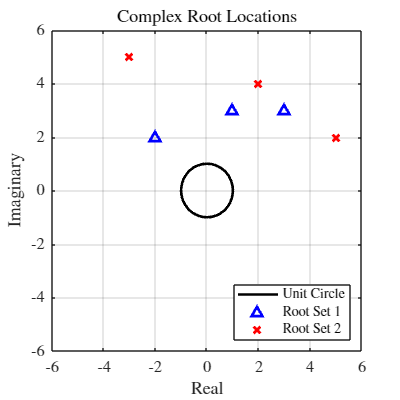

% Define two different sets of complex roots.
roots1 = [3+3i, 1+3i, -2+2i];
roots2 = [5+2i, 2+4i, -3+5i];

figure('Position',[0 0 400 400]);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the complex roots.
plot(real(roots1), imag(roots1), '^', 'Color', 'b', 'MarkerSize', 7, 'LineWidth', 2);
plot(real(roots2), imag(roots2), 'x', 'Color', 'r', 'MarkerSize', 7, 'LineWidth', 2);

grid on;
box on;
xlim([-6 6]);
xticks(-6:2:6);
ylim([-6 6]);
yticks(-6:2:6);
xlabel('Real');
ylabel('Imaginary');
legend('Unit Circle', 'Root Set 1', 'Root Set 2', 'Location', 'southeast');
title('Complex Root Locations');

Figure 1. Plot of complex root locations.